# Step Counter

clc, clear;
%Need to put it in the same timetable: same timebase
% Think about what data the classification needs
% Look at moving average for each variable (mean). Can add standard
% deviation. Look at minimum and max accel and orientation
% Break the data up into chunks
% 
%Create labels for classification

folder = "/MATLAB Drive/MobileSensorData";
fullMatFileName = fullfile(folder, "Step100.mat");
if~exist(fullMatFileName, "file")
    uiwait("%s does not exist", fullMatFileName);
else
    s=load(fullMatFileName);
    
end

dataAccel = s.Acceleration;
dataOrien = s.Orientation;
clear s;
[dataAccel, dataOrien] = DataClean(dataAccel, dataOrien);
features = retime(dataAccel, "regular","mean","TimeStep", seconds(2.5))

features = 31×3 timetable
           Timestamp              X          Y          Z   
    ________________________    ______    _______    _______

    27-Mar-2023 08:42:05.000     4.081     -7.342    0.67064
    27-Mar-2023 08:42:07.500    2.5573    -9.3751     1.0709
    27-Mar-2023 08:42:10.000    2.5696    -10.387      1.227
    27-Mar-2023 08:42:12.500    2.9875    -9.6394    0.46818
    27-Mar-2023 08:42:15.000    2.8919    -9.4492    0.32838
    27-Mar-2023 08:42:17.500    2.6016    -9.4786     1.4422
    27-Mar-2023 08:42:20.000    2.3256    -9.7903     1.2558
    27-Mar-2023 08:42:22.500    2.9436    -9.5739    0.67432
    27-Mar-2023 08:42:25.000    2.3278    -9.5988    0.82622
    2

features2 = retime(dataOrien, "regular","mean","TimeStep", seconds(2.5))

features2 = 31×3 timetable
           Timestamp               X         Y          Z   
    ________________________    _______    ______    _______

    27-Mar-2023 08:42:05.000    -36.741     48.33    -67.734
    27-Mar-2023 08:42:07.500      23.19    67.577    -51.588
    27-Mar-2023 08:42:10.000    -47.051    69.435    -65.737
    27-Mar-2023 08:42:12.500      4.456    68.417    -71.075
    27-Mar-2023 08:42:15.000      16.19    62.555    -88.294
    27-Mar-2023 08:42:17.500    -15.476    71.915    -100.67
    27-Mar-2023 08:42:20.000     81.016    71.173    -54.912
    27-Mar-2023 08:42:22.500     -26.61    71.539    -63.662
    27-Mar-2023 08:42:25.000     58.937    69.575    -69.565
    

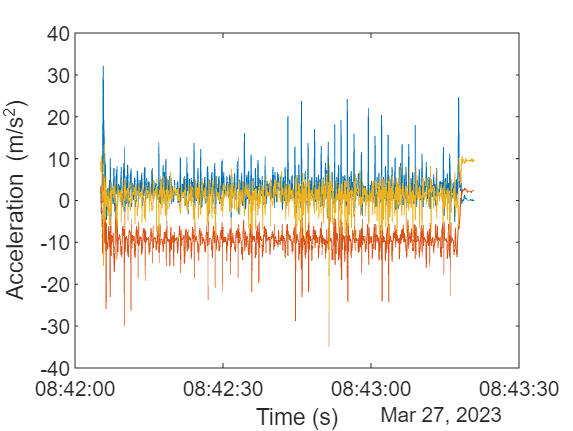

% labels = categorical(repmat("Walking",length(features),1))


% Seconds = datevec(dataAccel.Timestamp);
% NumSec = Seconds(:,6);
% Start = round(NumSec(1));
% End = round(NumSec(end));
% Duration = End-Start;
% Xaxis = 1:1:Duration;

plot(dataAccel.Timestamp, dataAccel.X);
hold on
plot(dataAccel.Timestamp, dataAccel.Y);
hold on
plot(dataAccel.Timestamp, dataAccel.Z);
hold off
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');

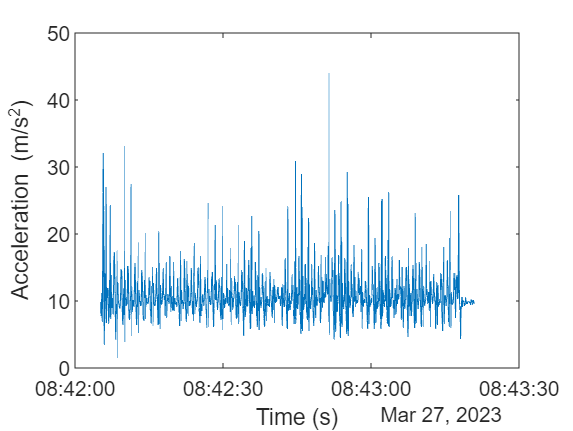

% xticklabels(Xaxis)





X = dataAccel.X;
Y = dataAccel.Y;
Z = dataAccel.Z;
mag = sqrt(sum(X.^2 + Y.^2 + Z.^2, 2));

plot(dataAccel.Timestamp, mag)
% xticklabels(Xaxis)
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');


magNoG = mag - mean(mag);

plot(dataAccel.Timestamp,magNoG);
% xticklabels(Xaxis)
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');


minPeakHeight = std(magNoG);

[pks,locs] = findpeaks(magNoG,'MINPEAKHEIGHT',minPeakHeight);

numSteps = numel(pks)

numSteps = 103

hold on;
plot(dataAccel.Timestamp(locs), pks, 'r', 'Marker', 'v', 'LineStyle', 'none');
title('Counting Steps');
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');
hold off;

m.AccelerationSensorEnabled = 0;

clear m;